clc;
clear all;

% Choose modulation order, ie the number of unique symbols that each
% subcarrier can hold
MOD_ORDER = 16;

MODULATION_FORMAT = 'QAM';

NUM_SYMBOLS_PER_CARRIER = 1e3;

NUM_SUBCARRIERS = 5;


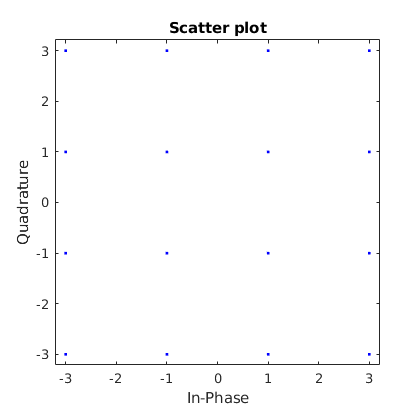

% Create QAM modulated signal, given number of symbols we want to generate

[modulated_signal, symbol_stream] = generateModSignal(NUM_SYMBOLS_PER_CARRIER, MOD_ORDER, NUM_SUBCARRIERS, MODULATION_FORMAT);

scatterplot(modulated_signal(:))

ofdm_signal = generateOFDMSignal(modulated_signal);
ofdm_signal = awgn(ofdm_signal,10,'measured');

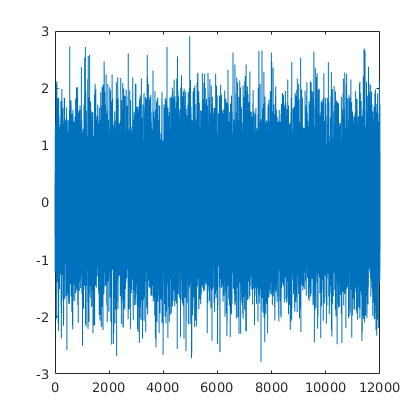

plot(ofdm_signal);

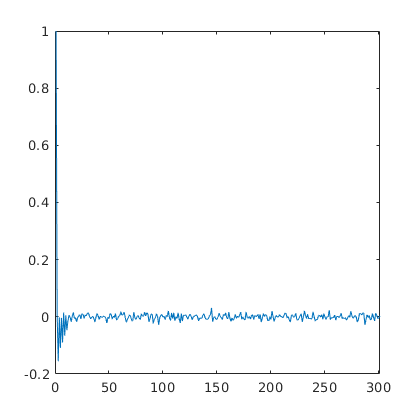

plot(autocorrelation(ofdm_signal, 300));

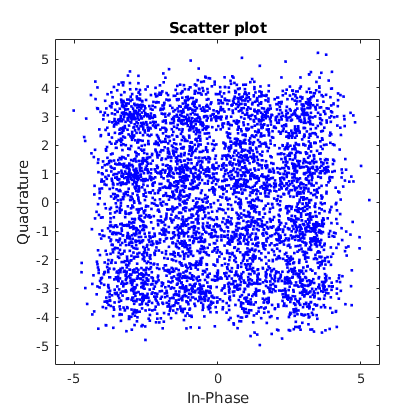

%make this into a demod to complex form, so I can plot the constellation

extracted_modulated_signal = demodOFDMSignal(ofdm_signal, NUM_SYMBOLS_PER_CARRIER, NUM_SUBCARRIERS);
scatterplot(extracted_modulated_signal(:))

extracted_stream = demodSignal(extracted_modulated_signal, MOD_ORDER, MODULATION_FORMAT);

[num_bit_errors, bit_error_rate, num_symbol_errors, symbol_error_rate] = calculateErrorRates(extracted_stream, symbol_stream);